## **Finite Element Method**

clc; 
clear;
syms a c h x

% No of elements
e = 3;
% No of Nodal points
n =e+1;

f = 4*x^2 - 2*x -4; % Source term
% Source vector Initialization 
f_x = sym(zeros(n, 1));


exact_sol_f = -2*x^2+x;

% numerical values for a, c, and h
a_num = 1;
c_num = -2;
% domain of X
x0 = 0;
xn = 1;
% Element length
h_num = (xn - x0) / e;

% At nodel point the value of x
X = (x0:h_num:xn)';

% Calculate f(x) for each x value symbolically and store in the vector
for i = 1:n
    f_x(i) = subs(f, x, X(i));
end
%disp(f_x);

% Define Shape Functions
phi_1 = 1 - x/h;
phi_2 = x/h;

phi_e = [phi_1; phi_2];

% Local stiffness matrix
KNM_local = zeros(2, 2, 'sym');
CNM_local = zeros(2, 2, 'sym');

for N = 1:2
    for M = 1:2
        % Integrate to get the local stiffness matrix
        KNM_local(N, M) = int(a * diff(phi_e(N), x) * diff(phi_e(M), x) - c * phi_e(N) * phi_e(M), x, 0, h);
        CNM_local(N, M) = int(-1* phi_e(N) * phi_e(M), x, 0, h);
    end
end

% Display the local stiffness matrix
disp('Local Stiffness Matrix some element e:');

Local Stiffness Matrix some element e:


disp(KNM_local);

$$\left(\begin{array}{cc} \frac{a}{h}-\frac{c\,h}{3} & -\frac{c\,h}{6}-\frac{a}{h}\\ -\frac{c\,h}{6}-\frac{a}{h} & \frac{a}{h}-\frac{c\,h}{3} \end{array}\right)$$

disp('Local C_NM Matrix some element e:');

Local C_NM Matrix some element e:


disp(CNM_local);

$$\left(\begin{array}{cc} -\frac{h}{3} & -\frac{h}{6}\\ -\frac{h}{6} & -\frac{h}{3} \end{array}\right)$$



% Substitute values into the local  matrices
KNM_local_sub = subs(KNM_local, {a, c, h}, {a_num, c_num, h_num});
CNM_local_sub = subs(CNM_local, h, h_num);

% Display the substituted local stiffness matrix
disp('Substituted values of a c and h in Local Stiffness Matrix:');

Substituted values of a c and h in Local Stiffness Matrix:


disp(KNM_local_sub);

$$\left(\begin{array}{cc} \frac{29}{9} & -\frac{26}{9}\\ -\frac{26}{9} & \frac{29}{9} \end{array}\right)$$

disp('Substituted value h in Local C_NM Matrix:');

Substituted value h in Local C_NM Matrix:


disp(CNM_local_sub);

$$\left(\begin{array}{cc} -\frac{1}{9} & -\frac{1}{18}\\ -\frac{1}{18} & -\frac{1}{9} \end{array}\right)$$


% Initialize global stiffness matrix
global_matrix_size = n; % each element has 2 nodal points
K_global = zeros(global_matrix_size);
C_global = zeros(global_matrix_size);

% Loop through each element
for element = 1:n-1

    % Assemble local stiffness matrix into global stiffness matrix
    start_index = element;
    end_index = element + 1;
    K_global(start_index:end_index, start_index:end_index) = K_global(start_index:end_index, start_index:end_index) + KNM_local_sub;
    C_global(start_index:end_index, start_index:end_index) = C_global(start_index:end_index, start_index:end_index) + CNM_local_sub;
end

% Display global stiffness matrix
disp('Global Stiffness Matrix:')

Global Stiffness Matrix:


disp(K_global);

    3.2222   -2.8889         0         0
   -2.8889    6.4444   -2.8889         0
         0   -2.8889    6.4444   -2.8889
         0         0   -2.8889    3.2222



disp('Global C Matrix:')

Global C Matrix:


disp(C_global);

   -0.1111   -0.0556         0         0
   -0.0556   -0.2222   -0.0556         0
         0   -0.0556   -0.2222   -0.0556
         0         0   -0.0556   -0.1111




%K_global_inverse=InverseTDMA(K_global)

CNM = C_global*f_x;

du_dx = -3;

% Dirichlet Boundary Conditions

K_global_D_bc = K_global;
g_x_D_bc = sym(zeros(n, 1));
GNM_D_bc= a_num*g_x_D_bc*du_dx;
RHS_D_bc = GNM_D_bc+CNM;

% Boundary Conditions1
u0 = 0;
K_global_D_bc(1,:)= [1,zeros(1, n-1)];  %u0 = 0
RHS_D_bc(1) = u0;  % RHS of equation

% Boundary Conditions2
un = -1;
K_global_D_bc(end,:)= [zeros(1, n-1), 1];  %un=-1
RHS_D_bc(end) = un;  % RHS of equation

% for finding inverse I'm using My TDMA inverse function
K_global_D_bc_inverse=InverseTDMA(K_global_D_bc);

%The Solution of Dirichlet B.C. using FEM is =
u_D_bc = double(K_global_D_bc_inverse*RHS_D_bc);% u at nodal points
disp("-------------------------------------------------------------")

-------------------------------------------------------------


disp("The Solution of Dirichlet B.C. using FEM is")

The Solution of Dirichlet B.C. using FEM is


myTable = table(X, u_D_bc, 'VariableNames', {'Nodal point', 'u'});
disp(myTable);

    Nodal point       u    
    ___________    ________

            0             0
      0.33333       0.11111
      0.66667      -0.22222
            1            -1



disp("-------------------------------------------------------------")

-------------------------------------------------------------


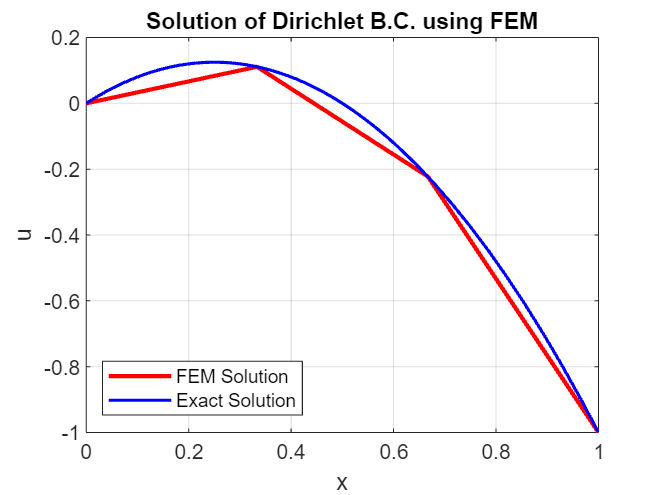

%Plot the FDM Solution and the actual solution
figure;
plot(X, u_D_bc, "r", "LineWidth", 2, "DisplayName", "FEM Solution"); 
hold on;
fplot(x, exact_sol_f, [0 1], "b", "LineWidth", 1.5, "DisplayName", "Exact Solution");
xlabel("x");
ylabel("u");
title("Solution of Dirichlet B.C. using FEM");
legend('Location', 'southwest');
grid on;


du_dx = -3; % at end point x = 1

% Neumann boundary Conditions
K_global_n_bc = K_global;
g_x_n_bc = sym(zeros(n, 1));
g_x_n_bc(end)=1;

GNM_n_bc= a_num*g_x_n_bc*du_dx;
RHS_n_bc = GNM_n_bc+CNM;

% Boundary Conditions1
u0 = 0;
K_global_n_bc(1,:)= [1,zeros(1, n-1)];  %u0 = 0
RHS_n_bc(1) = u0;  % RHS of equation


% for finding inverse I'm using My TDMA inverse function
K_global_n_bc_inverse=InverseTDMA(K_global_n_bc);

%The Solution of Dirichlet B.C. using FEM is =
u_n_bc = double(K_global_n_bc_inverse*RHS_n_bc);% u at nodal points
disp("-------------------------------------------------------------")

-------------------------------------------------------------


disp("The Solution of Neumann B.C. using FEM with Phantom Node is");

The Solution of Neumann B.C. using FEM with Phantom Node is


Table2 = table(X, u_n_bc, 'VariableNames', {'Nodal point', 'u'});
disp(Table2);

    Nodal point       u    
    ___________    ________

            0             0
      0.33333       0.11111
      0.66667      -0.22222
            1            -1



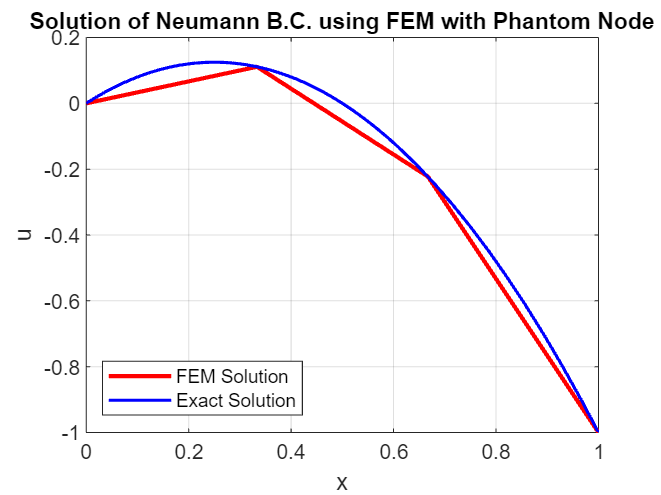


%Plot the FDM Solution and the actual solution
figure;
plot(X, u_n_bc, "r", "LineWidth", 2, "DisplayName", "FEM Solution"); 
hold on;
fplot(x, exact_sol_f, [0 1], "b", "LineWidth", 1.5, "DisplayName", "Exact Solution");
xlabel("x");
ylabel("u");
title("Solution of Neumann B.C. using FEM with Phantom Node");
legend('Location', 'southwest');
grid on;

function [X] = InverseTDMA(T)
    [n, ~] = size(T);

    % Check if T is tridiagonal
    for a = 1:n
        for b = 1:n
            if a ~= b && a ~= b - 1 && a ~= b + 1 && T(a, b) ~= 0
                disp('The given matrix is not a tridiagonal matrix');
                %n = 0;
                return;
            end
        end
    end

    B = eye(n); % Initialize B as an identity matrix

    % Decompose T using row operations
    for i = 2:n
        T(i, i - 1) = T(i, i - 1) / T(i - 1, i - 1);
        T(i, i) = T(i, i) - T(i, i - 1) * T(i - 1, i);
    end

    % Perform row operations on B
    for j = 1:n
        for i = 2:n
            B(i, j) = B(i, j) - T(i, i - 1) * B(i - 1, j);
        end
    end

    X = zeros(n, n); % Initialize X as a zero matrix

    % Back substitution to find the inverse matrix X
    for p = 1:n
        X(n, p) = B(n, p) / T(n, n); % Find the last element of each column
        for q = n - 1:-1:1
            X(q, p) = (B(q, p) - T(q, q + 1) * X(q + 1, p)) / T(q, q); % Compute elements in reverse order
        end
    end

    %disp('The inverse for the given matrix Tridigonal matrix, computed using the TDMA, is:');
end

